% Define system components
oqpskmod = comm.OQPSKModulator('BitInput', true);
oqpskdemod = comm.OQPSKDemodulator('BitOutput', true);
channel = comm.AWGNChannel('EbNo', 20, 'BitsPerSymbol', 2);

% Define raised cosine filters
span = 1;                 % Filter span (number of symbols)
samplesPerSymbol = 8;      % Samples per symbol
rolloff = 0.5;               % Rolloff factor

txFilter = comm.RaisedCosineTransmitFilter( ...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'OutputSamplesPerSymbol', samplesPerSymbol);

rxFilter = comm.RaisedCosineReceiveFilter( ...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'InputSamplesPerSymbol', samplesPerSymbol, ...
    'DecimationFactor', samplesPerSymbol);

% Generate a random binary sequence
numBits = 2^12;
data = randi([0 1], numBits, 1);

% Modulate the signal
txSignal = oqpskmod(data);

% Filter the signal at the transmitter
txFilteredSignal = txFilter(txSignal);

% Introduce a random phase shift in the channel
randomPhaseShift = 2 * pi * rand;  % Random phase shift in the range [0, 2π]
phaseShiftDeg = randomPhaseShift/pi * 180;
txSignalWithPhaseShift = txFilteredSignal * exp(1j * randomPhaseShift);

% Pass the phase-shifted signal through the AWGN channel and filter
rxSignal = rxFilter(channel(txSignalWithPhaseShift));

rxSignal_noShift = rxFilter(channel(txFilteredSignal));

# Time-Series

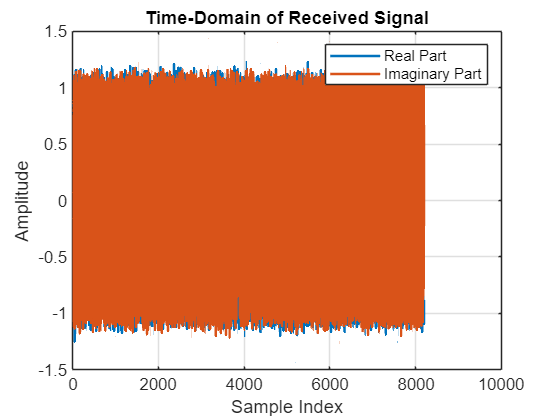

figure;
plot(real(rxSignal), 'LineWidth', 1.5,'DisplayName','Real Part');
hold on;
plot(imag(rxSignal), 'LineWidth', 1.5,'DisplayName','Imaginary Part');
title('Time-Domain of Received Signal');
xlabel('Sample Index');
ylabel('Amplitude');
legend();
grid on;
hold off;

# Constellation

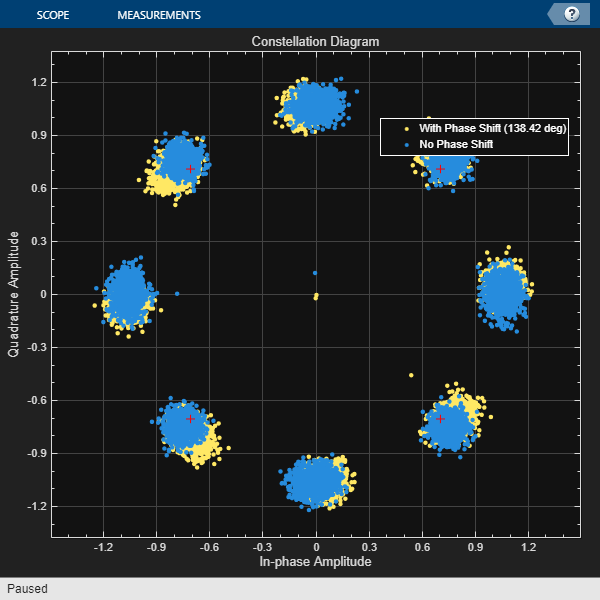

constDiagram = comm.ConstellationDiagram( ...
    'ShowLegend', true, ...
    'Title', 'Constellation Diagram', ...
    'ChannelNames', { ...
        sprintf('With Phase Shift (%.2f deg)', phaseShiftDeg), ...
        'No Phase Shift'});

constDiagram([rxSignal, rxSignal_noShift]);

# Eye-Diagram

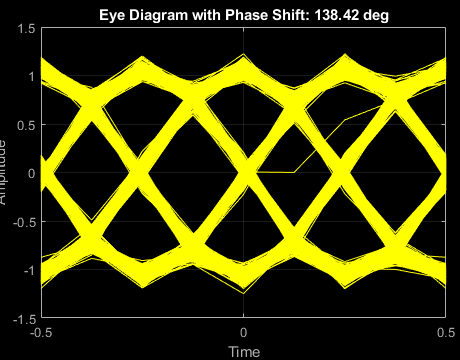

figure;
eyediagram(real(rxSignal), samplesPerSymbol * span);
title(sprintf('Eye Diagram with Phase Shift: %.2f deg', phaseShiftDeg));  % Dynamic title
xlabel('Time');
ylabel('Amplitude');
grid on;